# Signal distributions and PR

This document includes plots that intend to connect the distributions of signal ${\left(\Delta \mu_i \right)}^2$ with the PR and the log-domain variance.

Specifically, this attempts to address two points:

- What the signal distributions look like for animals with low and high PR

- How Figure 4f (the PR histograms) look like for all the animals with "high quality" sessions, and how they look like using log-domain variance instead of PR.

org = Org;
org.init;

## What the signal distributions look like for animals with low and high PR

To be able to observe the signal distributions at a point on the tuning curve, I chose an arbitrary bin in the middle of the track (bin #10). For each animal, I chose one example session from which to get the signal distribution for the chosen bin. After trying to make sense of 12 overlayed histograms I gave up and put the histograms into the rows of a heatmap. Each row is one example session from each animal and is labeled by the PR of the chosen bin in that session. The rows are sorted by the PR value. A prominent feature of this plot is that stronger positive tails of the signal distribution lead to lower PR values.

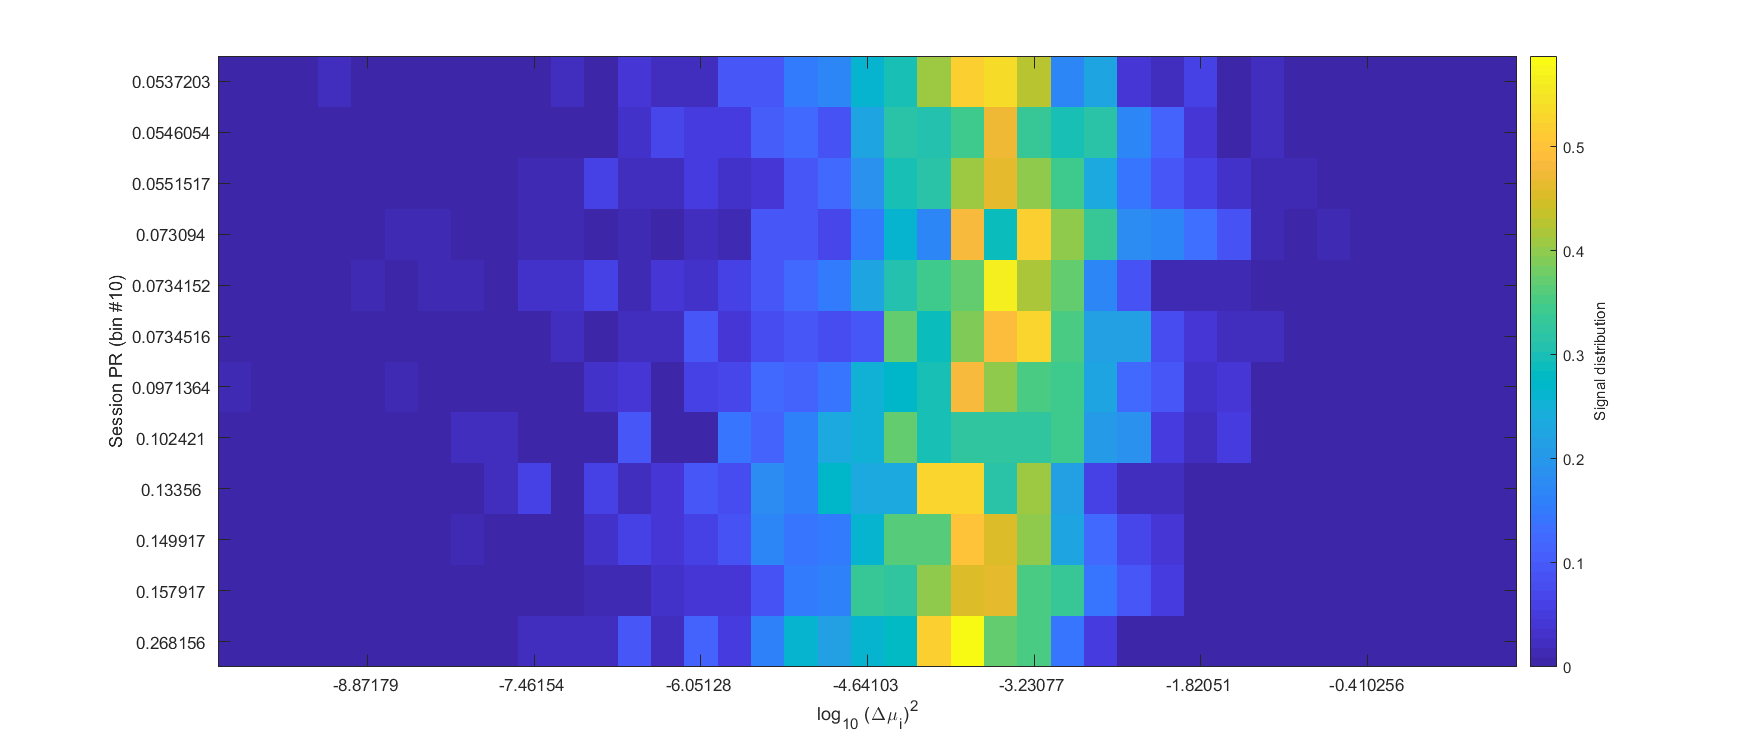

mice = SessManager.usable_mice;
mice = unique(mice);
special_sess_ix =SessManager.special_sessions_usable_index(mice);
chosen_bin = 10;
edges = linspace(-10,1,40);


probs = zeros(numel(mice), numel(edges)-1);
sess_prs = zeros(1,numel(mice));
figure('Position',[0,0,700,300]*2);
for i = 1:numel(mice)
    signals = org.sess_by_bins('dmus', special_sess_ix(i)).^2;
    %subplot(numel(mice),1,i);
    %subplot(1,numel(mice), i);
    %histogram(log10(signals(:,chosen_bin)), 'Normalization','pdf');
    probs(i,:) = histcounts(log10(signals(:,chosen_bin)), edges,'Normalization','pdf');
    my_prs = org.sess_by_bins('signal_density', special_sess_ix(i));
    sess_prs(i) = my_prs(chosen_bin);
    %hold on;
    %title(mice{i});
    %xlabel 'log_{10} (\Delta\mu_i)^2'
    %ylabel 'pdf'
    %ylabel(mice{i});
    %xlim([-10 -1]);
    %ylim([0 0.6]);
end
%xlabel 'log_{10} (\Delta\mu_i)^2'
[sess_prs_sorted, ord] = sort(sess_prs);
probs = probs(ord,:);
imagesc(probs);

ax = gca;
idx = ax.XTick;
ax.XTickLabels = edges(idx);
ax.YTick = 1:numel(mice);
ax.YTickLabel = sess_prs_sorted;

xlabel 'log_{10} (\Delta\mu_i)^2'
ylabel(sprintf('Session PR (bin #%d)', chosen_bin));
h_ = colorbar; ylabel(h_, 'Signal distribution');


fprintf('Mice in order of rising PR:\n');

Mice in order of rising PR:


disp(mice(ord));

  Columns 1 through 6

    'Mouse2023'    'Mouse2024'    'Mouse2021'    'Mouse2019'    'Mouse2028'    'Mouse2012'

  Columns 7 through 12

    'Mouse2011'    'Mouse2029'    'Mouse2025'    'Mouse2026'    'Mouse2022'    'Mouse2010'



### The PR in a single bin & session correlates with the aggregated PR of the mouse

The PR in a particular bin and a particular example session per mouse correlated with the PR of the mouse aggregated over all bins and sessions.

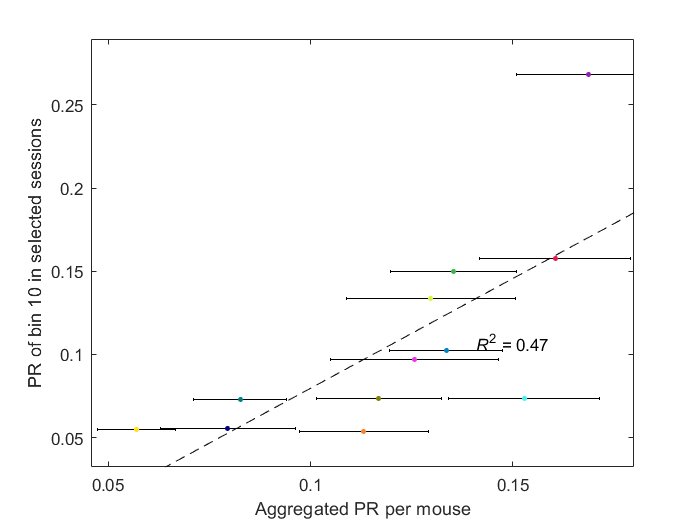

figure;
[agg_pr, agg_pr_conf] = Org.agg(org.mouse, org.sess_prop.signal_density, org.sess_prop_conf.signal_density);
PanelGenerator.plot_regress(agg_pr(:), sess_prs(:), agg_pr_conf(:), 0*agg_pr_conf(:), mice, 'k', 'dotsize', 10);
xlabel 'Aggregated PR per mouse'
ylabel(sprintf('PR of bin %d in selected sessions', chosen_bin));

### The previous plot, sorted by the log-domain variance

The variance treats both the positive and negative tails equally, despite the fact that the negative tails likely represent noise (from non-coding neurons).

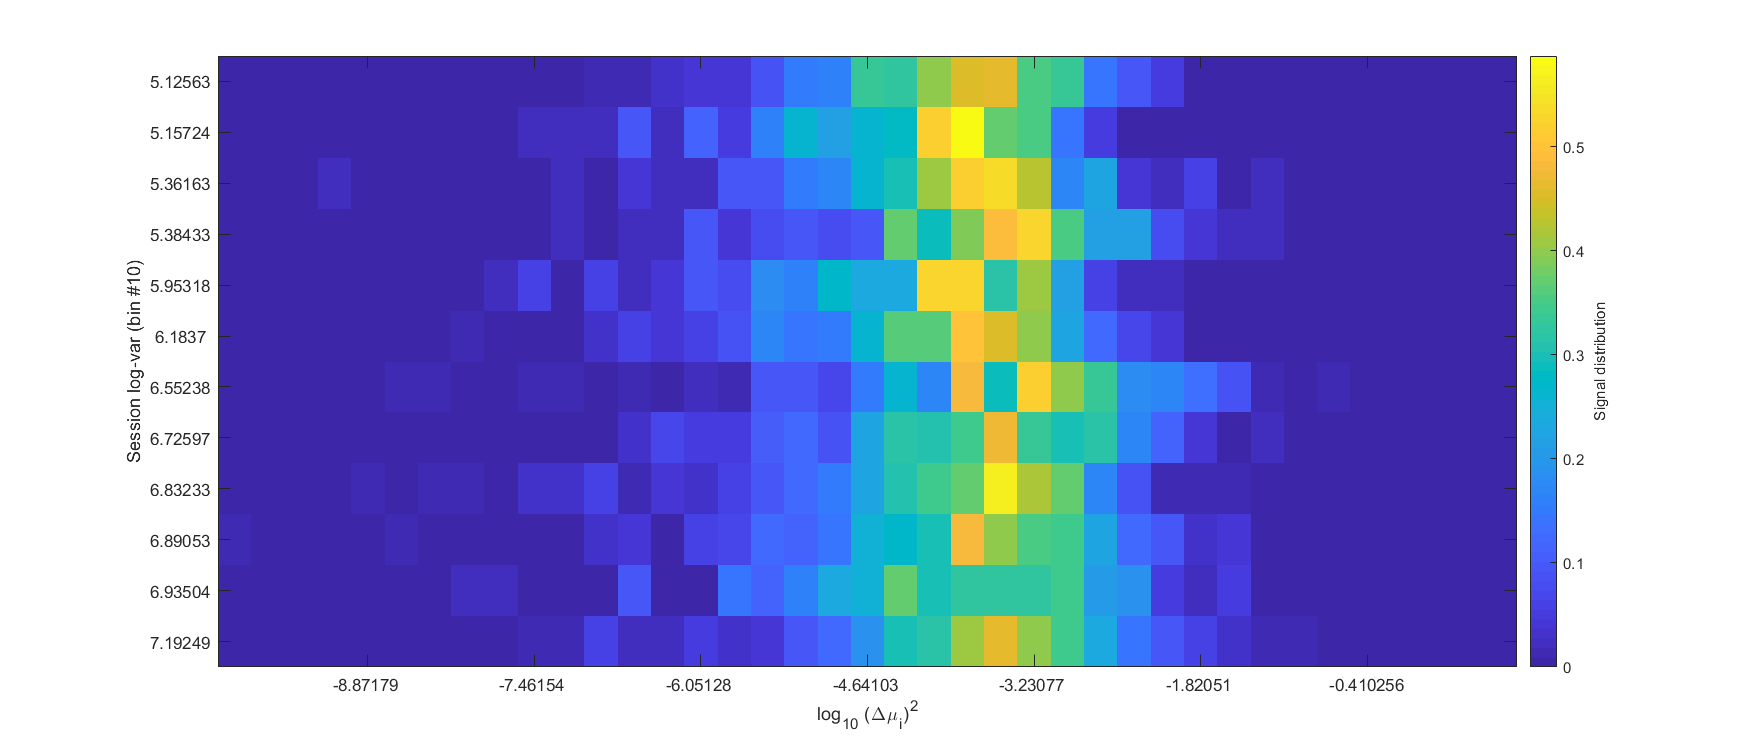

mice = SessManager.usable_mice;
special_sess_ix =SessManager.special_sessions_usable_index(mice);
chosen_bin = 10;
edges = linspace(-10,1,40);


probs = zeros(numel(mice), numel(edges)-1);
sess_prs = zeros(1,numel(mice));
figure('Position',[0,0,700,300]*2);
for i = 1:numel(mice)
    signals = org.sess_by_bins('dmus', special_sess_ix(i)).^2;
    %subplot(numel(mice),1,i);
    %subplot(1,numel(mice), i);
    %histogram(log10(signals(:,chosen_bin)), 'Normalization','pdf');
    probs(i,:) = histcounts(log10(signals(:,chosen_bin)), edges,'Normalization','pdf');
    my_prs = org.sess_by_bins('signal_log_var', special_sess_ix(i));
    sess_prs(i) = my_prs(chosen_bin);
    %hold on;
    %title(mice{i});
    %xlabel 'log_{10} (\Delta\mu_i)^2'
    %ylabel 'pdf'
    %ylabel(mice{i});
    %xlim([-10 -1]);
    %ylim([0 0.6]);
end
%xlabel 'log_{10} (\Delta\mu_i)^2'
[sess_prs, ord] = sort(sess_prs);
probs = probs(ord,:);
imagesc(probs);

ax = gca;
idx = ax.XTick;
ax.XTickLabels = edges(idx);
ax.YTick = 1:numel(mice);
ax.YTickLabel = sess_prs;

xlabel 'log_{10} (\Delta\mu_i)^2'
ylabel(sprintf('Session log-var (bin #%d)', chosen_bin));
h_ = colorbar; ylabel(h_, 'Signal distribution');

## How Figure 4f (the PR histograms) look like for all the animals with "high quality" sessions

These histograms are identical to the ones from Figure 4f but include more mice. The mice are sorted by their aggregated PR. I did not turn these into a heatmap because the trend is sufficiently distinguishable.

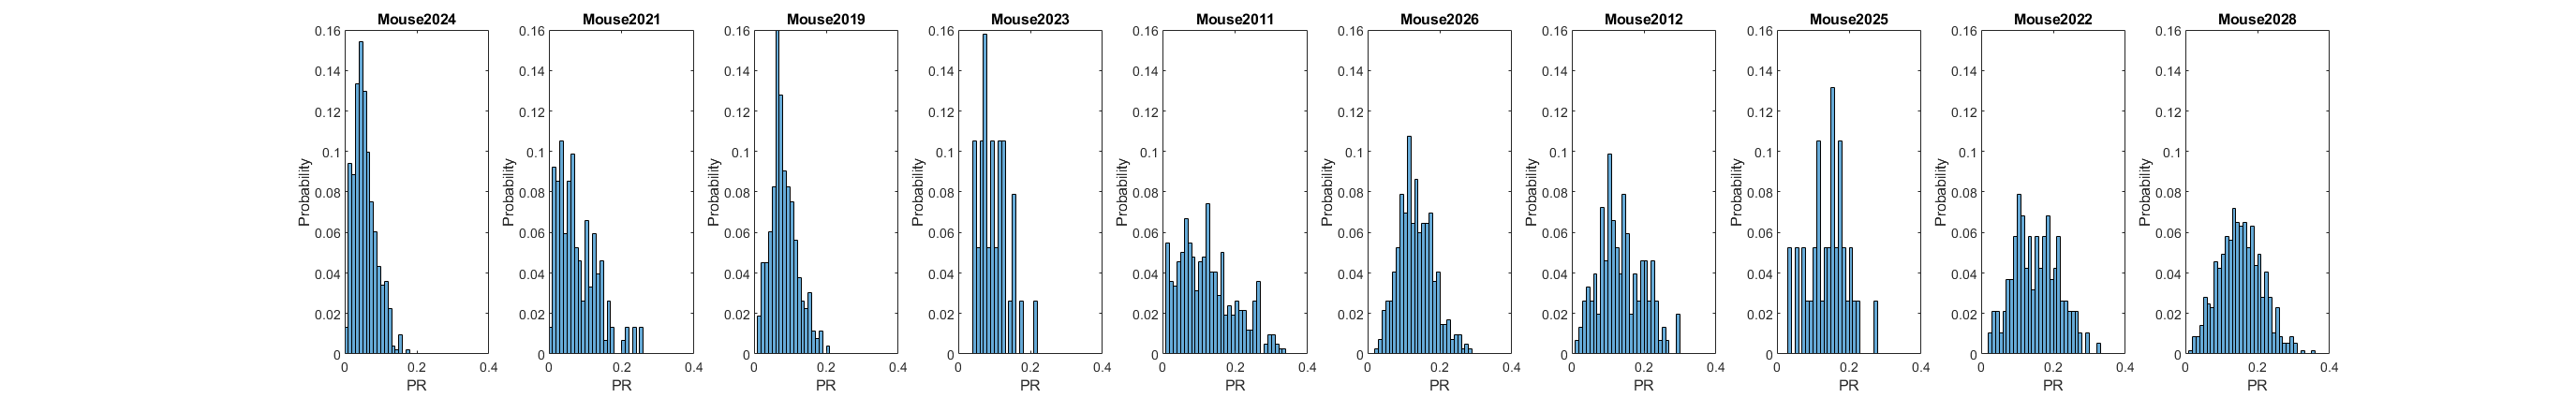

mice = SessManager.highqual_mice;%unique(org.mouse);
f_ = SessManager.highqual_filt_from_usable;
pr_per_mouse = Org.agg(org.mouse(f_), org.sess_prop.signal_density(f_), org.sess_prop_conf.signal_density(f_));
[pr_per_mouse_sorted, ord] = sort(pr_per_mouse);
mice_sorted = mice(ord);
%edges = 0:0.01:0.4;%linspace(0,0.4,20);
binwidth = 0.01;

figure('Position',[0,0,1100,170]*2);
for i = 1:numel(mice_sorted)
    subplot(1,numel(mice_sorted), i);
    %special_sess_ix = SessManager.special_sessions_usable_index(mice_sorted{i});
    %pr_by_bins = org.sess_by_bins('signal_density', special_sess_ix);
    pr_by_bins = org.mouse_all_sess('signal_density', {mice_sorted{i}, 'restrict'});
    pr_by_bins = pr_by_bins(:);
    pr_by_bins(isnan(pr_by_bins)) = [];
    histogram(pr_by_bins, 'BinWidth', binwidth, 'Normalization','probability');
    xlabel 'PR';
    ylabel 'Probability';
    xlim([0,0.4]);
    title(mice_sorted{i});
    ylim([0,0.16]);
end

### The previous histograms but using the log-domain variance

I kept the same order as the previous set of histograms. The trend is a lot weaker here. It is even hard to discern that it is in the reverse direction to PR.

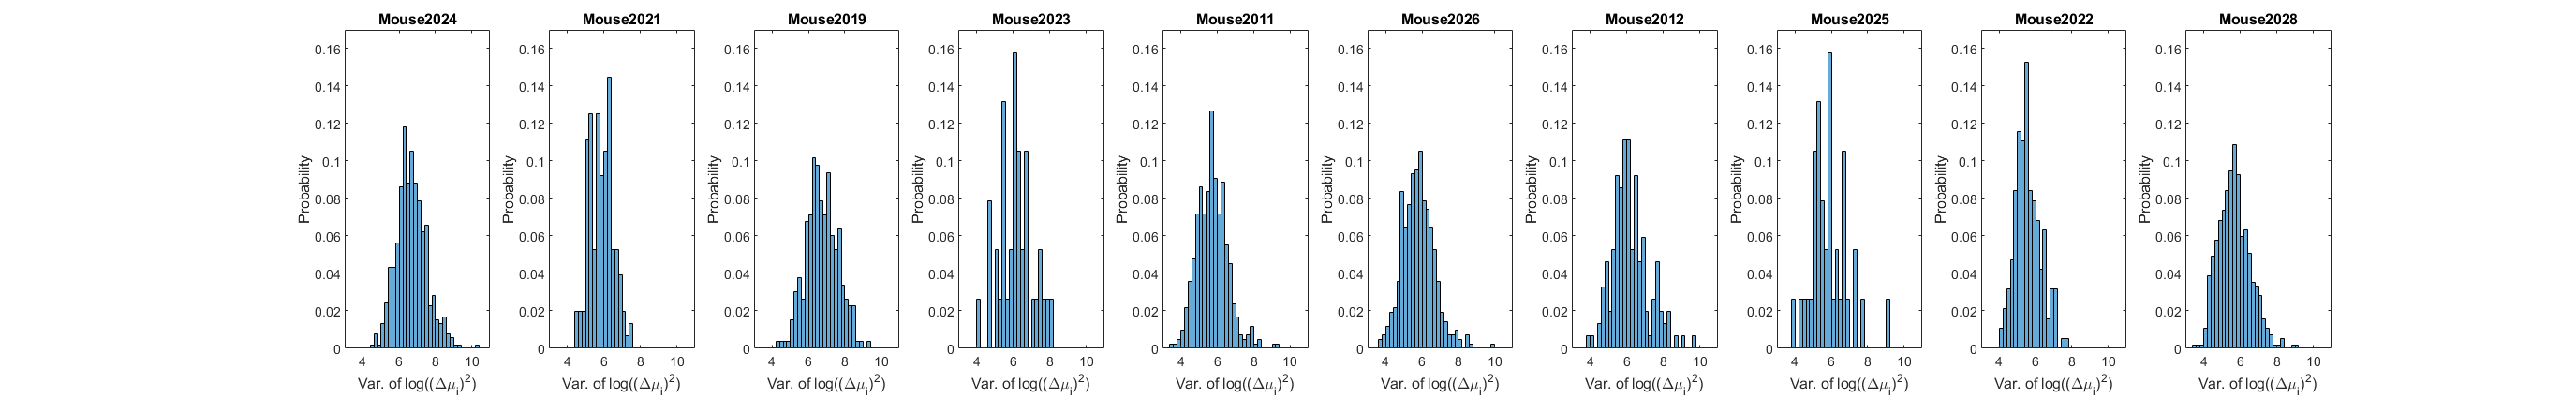

mice = SessManager.highqual_mice;%unique(org.mouse);
f_ = SessManager.highqual_filt_from_usable;
pr_per_mouse = Org.agg(org.mouse(f_), org.sess_prop.signal_density(f_), org.sess_prop_conf.signal_density(f_));
[pr_per_mouse_sorted, ord] = sort(pr_per_mouse);
mice_sorted = mice(ord);
%edges = linspace(4,12,41); %0.2 bin width
binwidth = 0.2;

figure('Position',[0,0,1100,170]*2);
for i = 1:numel(mice_sorted)
    subplot(1,numel(mice_sorted), i);
    %special_sess_ix = SessManager.special_sessions_usable_index(mice_sorted{i});
    %log_var_by_bins = org.sess_by_bins('signal_log_var', special_sess_ix);
    log_var_by_bins = org.mouse_all_sess('signal_log_var', {mice_sorted{i}, 'restrict'});
    log_var_by_bins = log_var_by_bins(:);
    log_var_by_bins(isnan(log_var_by_bins)) = [];
    histogram(log_var_by_bins, 'BinWidth', binwidth, 'Normalization','probability');
    xlabel 'Var. of log((\Delta\mu_i)^2)';
    ylabel 'Probability';
    xlim([3,11]);
    title(mice_sorted{i});
    ylim([0,0.17]);
end

### The relationship between the PR and the log-doimain variance

As a reminder, here is what the inverse relationship between the PR and the log-domain variance looks like across mice.

figure;
org.correlogram('signal_density', 'signal_log_var', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations signal_density vs. signal_log_var: adj. R^2 = 0.517
Pearson: -0.755, p = 1.153822e-02, *
Spearman: -0.648, p = 4.904263e-02, *
Kendall: -0.467, p = 7.255015e-02, n.s


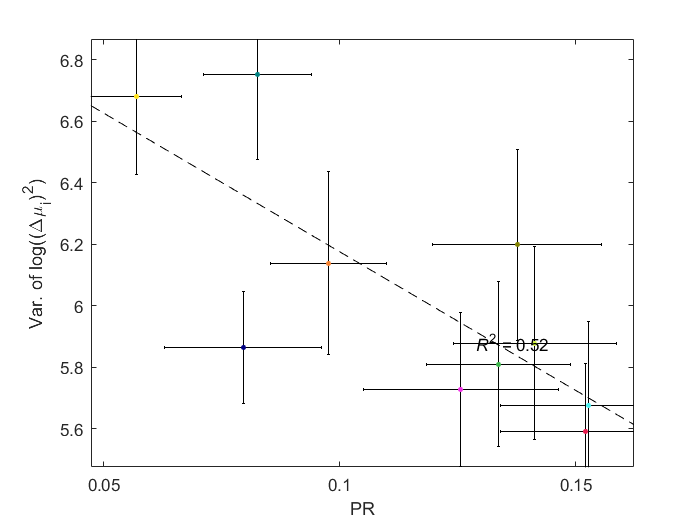

xlabel 'PR';
ylabel 'Var. of log((\Delta\mu_i)^2)';